# Network Milestone - Alexander Wang (aw3494), Nick Fiorovanti (nef46)

## Step 1. Set up Network Representation

% Number of individuals
N = 100;

% Random symmetric matrix
network = randi([0, 1], N);
network = triu(network, 1);
network = network + network';

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Create random ages for individuals in contact network
age = ones(N,1); 
for p = 1:size(age,1)
    age(p) = randi(80);
end

% Randomly assign a few individuals as Infected
num_initially_infected = 0.05*N;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;

% Initial stats:
initial_infected_proportion = sum(state)/N; 
initial_susceptible_proportion = sum(state==0)/N;

## Step 2. Simulate

% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 365;                                 % days
expose_prob = 0.05;                             % exposure prob
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_exposed = zeros(num_days, 1);               % Vector of exposed individuals each day
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
hospitalization_rate = 0.15;                    %https://gis.cdc.gov/grasp/COVIDNet/COVID19_3.html 
% positive_rate = 0.12875/7;  % by week           % Percent Positive Testing: averaged peaks of % positive weekly https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00
% MAKE ASSUMPTION - IF EACH EXPOSED INDIVIDUAL AT-HOME TESTS, AND THEN TESTS POSITIVE, THEY
% SOCIAL DISTANCE AND CANNOT INFECT OTHERS
% ORRRRRR
socialdist_prob = 0.5;                         % no statistic for social distancing probability when healthy, so we made it 50/50 chance
% 0.75 - quarantining rate  - https://thehill.com/changing-america/well-being/medical-advances/491760-3-in-4-americans-say-they-are-self-isolating-in/#:~:text=Approximately%2075%20percent%20of%20U.S.%20residents%20are%20self-isolating,coronavirus%20and%20is%20being%20enforced%20across%20the%20country.
% find quarantining rate to find acceptable loss of individuals

% Hosp death rate approximated from: 
% https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm
hosp_death_rate_29 = 0.03/7;
hosp_death_rate_59 = 0.07/7;
hosp_death_rate_plus = 0.18/7;

Other rates

% hospitalization_rate = 0.0015;                  % hospitalization rate https://www.nytimes.com/interactive/2023/us/covid-cases.html

%hospitalization_rate = 1.2/100000; % https://www.nytimes.com/interactive/2023/us/covid-cases.html

% hospitalization_rate = 0.3; % [https://www.economist.com/graphic-detail/2021/03/13/our-covid-19-model-estimates-odds-of-hospitalisation-and-death](https://www.economist.com/graphic-detail/2021/03/13/our-covid-19-model-estimates-odds-of-hospitalisation-and-death)

% death_rate = 0.1625;                % percent deaths: averaged peaks of % death attributed to covid https://covid.cdc.gov/covid-data-tracker/#trends_weeklyhospitaladmissions_testpositivity_00

% death_rate = 0.3/100000 % https://www.nytimes.com/interactive/2023/us/covid-cases.html

% death_rate = 1.1/100 % https://coronavirus.jhu.edu/data/mortality

% death_rate = 0.06; % https://ourworldindata.org/mortality-risk-covid

% hosp_death_rate = 0.10/7; % by week, % [https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm](https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm)

% death_rate = 0.0028;                          % OLD DEATH RATE: gross mortality rate https://www.worldometers.info/coronavirus/coronavirus-death-rate/

% quarantining_rate = 0.75;                       % quarantining rate  - https://thehill.com/changing-america/well-being/medical-advances/491760-3-in-4-americans-say-they-are-self-isolating-in/#:~:text=Approximately%2075%20percent%20of%20U.S.%20residents%20are%20self-isolating,coronavirus%20and%20is%20being%20enforced%20across%20the%20country.

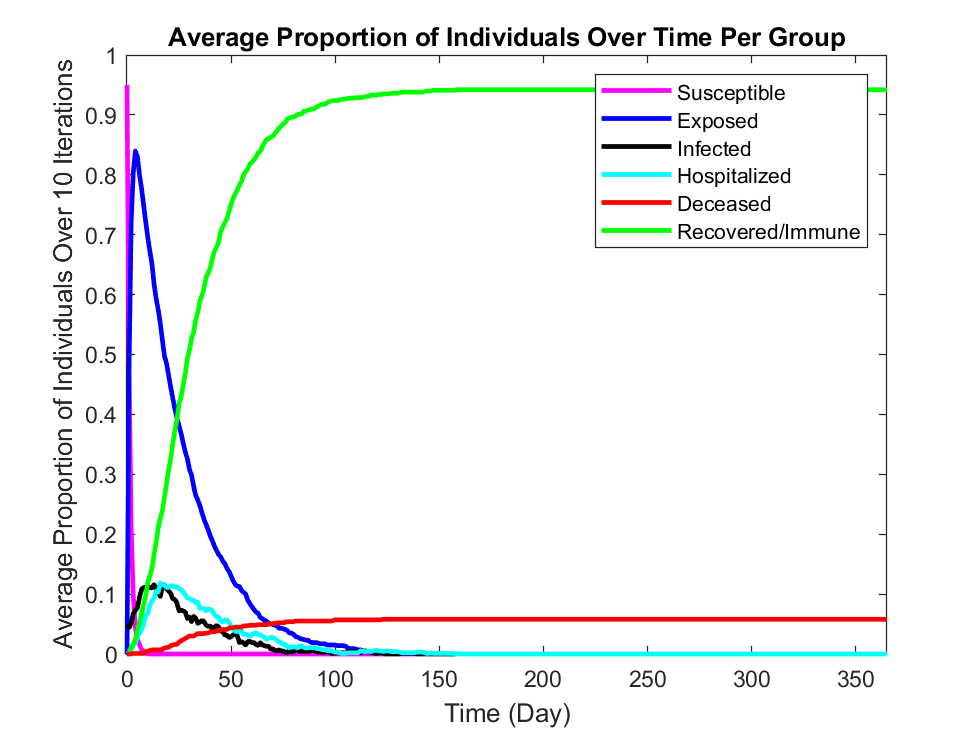

% Store infected/susceptible state to recall for all iterations
state_orig = state;

% RECAP: SUSCEPTIBLE = 0, INFECTED = 1, EXPOSED = 2, HOSPITALIZED = 3,
% RECOVERED/IMMUNE = 4, DEAD = NaN

% Repeat model for 10 iterations to average findings
for l = 1:10

    % initialize the iteration state of susceptible and infected to original state of infection
    state = state_orig; 
    
    % For each day in the year
    for day = 1:num_days      
        
        % For each individual in the contact network
        for i = 1:N                                 
            
            % If the individual is infected
            if state(i) == 1
                
                % Find the other individuals in the network they are in
                % contact with 
                contacts = find(network(i, :));     
                
                % For all contacts in network 
                for j = contacts               
                    
                    % Randomly generate a number to decide chance of
                    % contact becoming exposed if susceptible
                    exposed_diceroll = rand;

                    % If contact is susceptible
                    if state(j) == 0

                       % generate random chance for not social distancing
                       social_dist_diceroll = rand; 
                       
                       % If individual didn't social distance
                       if social_dist_diceroll > socialdist_prob

                            % See if the probability is within the expected for
                            % exposure
                            if exposed_diceroll < expose_prob 
    
                                % If so, susceptible individual becomes exposed
                                % to COVID
                                state(j) = 2; 
                            end
                       end
                    end
                end

                % now move onto the current infected patient 

                % Since the patient is infected, there is a chance they
                % will recover 
                
                % Randomly generate this chance
                recovery_diceroll = rand;

                % Randomly generate a chance for hospitalization as well 
                hospitalized_diceroll = rand;
                % IMMUNITY LASTS ABOUT 500 DAYS (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                % If recovery chance is within expected probability
                if recovery_diceroll < recover_prob

                    % Infected individual becomes susceptible again
                    % (disregard short-term immunity as individuals have
                    % been found to get covid multiple times) 
                    state(i) = 4; 
                
                    % MAKE ASSUMPTION THAT IF PEOPLE ARE SICK, THEY'LL GO
                    % TO HOSPITAL - ONLY PLACE THEY WOULD DIE
%                 % If chance is not within recovery and expectation for death
%                 elseif recovery_diceroll > (1-death_rate) && hospitalized_diceroll > hospitalization_rate
%                    
%                     % individual gets removed from the network
%                     state(i) = NaN;                           
%                 
                % if chance not within recovery and hospitalization is
                % probable
                elseif recovery_diceroll > recover_prob && hospitalized_diceroll < hospitalization_rate

                    % infected individual instead becomes hospitalized
                    state(i) = 3;
                end
                
            % If the individual is not infected, but is exposed, 
            elseif state(i) == 2 
                
                % Generate random chance for individual to become infected
                infected_diceroll = rand; 

                % If chance is within expected
                if infected_diceroll <  infect_prob

                    % Convert exposed individual to infected
                    state(i) = 1;
                end

            % If individual is hospitalized
            elseif state(i) == 3   
                
                % Generate random recovery chance
                recovery_diceroll = rand; 

                % Generate random hospitalization chance
                hospitalized_diceroll = rand;

                % Generate random death chance
                reaper_diceroll = rand;
                
                % IMMUNITY FOR 500 days (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                % If recovery is expected
                if recovery_diceroll < recover_prob 
                    
                    % Hospitalized individual becomes susceptible and can
                    % go home
                    state(i) = 4;
                
                % If individual is still symptomatic and expected by chance
                elseif hospitalized_diceroll < hospitalization_rate

                    % Remain in hospital
                    state(i) = 3; 
                end

                if age(i) <= 29
                    if reaper_diceroll < hosp_death_rate_29
                        state(i) = NaN;
                    end
                elseif age(i) <= 59
                    if reaper_diceroll < hosp_death_rate_59
                        state(i) = NaN;
                    end
                else 
                    if reaper_diceroll < hosp_death_rate_plus
                        state(i) = NaN;
                    end
                end
%                 % If individual is hospitalized, and expected for death
%                 elseif reaper_diceroll < hosp_death_rate 
%                     state(i) = NaN;
%                 end 

            % If susceptible, 
            elseif state(i) == 0 
                social_dist_diceroll = rand; 
                if social_dist_diceroll > socialdist_prob % then did not social distance and gets exposed to covid-19
                    state(i) = 2;
                end
            end
        end  
        % Record the number of exposed and infected individuals
        num_susceptible(day) = sum(state == 0);
        num_infected(day) = sum(state == 1);
        num_exposed(day) = sum(state == 2);
        num_hospitalized(day) = sum(state == 3);
        num_immune(day) = sum(state == 4); 
        num_deceased(day) = sum(isnan(state));
    end

% Store all of the simulated data for this iteration in the accumulation
% variables
num_exposed_accumulated(l,:) = num_exposed';
num_infected_accumulated(l,:) = num_infected';
num_susceptible_accumulated(l,:) = num_susceptible';
num_deceased_accumulated(l,:) = num_deceased'; 
num_hospitalized_accumulated(l,:) = num_hospitalized';
num_immune_accumulated(l, :) = num_immune';
end
% 
% % Plot the number of exposed and infected individuals over time
% figure;
% 
% % Plot susceptible
% plot(0:num_days, [initial_susceptible_proportion mean(num_susceptible_accumulated)/N],'-o', 'Color', 'Magenta', 'DisplayName', 'Susceptible', 'LineWidth', 1);
% hold on 
% % Plot exposed proportion 
% plot(0:num_days, [0 mean(num_exposed_accumulated)/N], '-o','Color', 'Blue', 'DisplayName', 'Exposed', 'LineWidth', 1);
% 
% % Plot infectious proportion
% plot(0:num_days, [initial_infected_proportion mean(num_infected_accumulated)/N], '-o','Color', 'Black', 'DisplayName', 'Infected', 'LineWidth', 1);
% 
% % Plot hospitalized proportion
% plot(0:num_days, [0 mean(num_hospitalized_accumulated)/N], '-o','Color', 'Cyan', 'DisplayName', 'Hospitalized', 'LineWidth', 1)
% 
% % Plot deceased proportion
% plot(0:num_days, [0 mean(num_deceased_accumulated)/N], '-o','Color', 'Red', 'DisplayName', 'Deceased', 'LineWidth', 1)
% 
% % Plot immune proportion
% plot(0:num_days, [0 mean(num_immune_accumulated)/N], '-o','Color', 'Green', 'DisplayName', 'Recovered/Immune', 'LineWidth', 1)
% % Label figure
% xlabel('Time (Day)');
% ylabel('Average Proportion of Individuals Over 10 Iterations');
% xlim([0 num_days])
% title('Average Proportion of Individuals Over Time Per Group')
% legend()

% Plot the number of exposed and infected individuals over time
figure;

% Plot susceptible
plot(0:num_days, [initial_susceptible_proportion mean(num_susceptible_accumulated)/N], 'Color', 'Magenta', 'DisplayName', 'Susceptible', 'LineWidth', 2);
hold on 
% Plot exposed proportion 
plot(0:num_days, [0 mean(num_exposed_accumulated)/N], 'Color', 'Blue', 'DisplayName', 'Exposed', 'LineWidth', 2);

% Plot infectious proportion
plot(0:num_days, [initial_infected_proportion mean(num_infected_accumulated)/N], 'Color', 'Black', 'DisplayName', 'Infected', 'LineWidth', 2);

% Plot hospitalized proportion
plot(0:num_days, [0 mean(num_hospitalized_accumulated)/N], 'Color', 'Cyan', 'DisplayName', 'Hospitalized', 'LineWidth', 2)

% Plot deceased proportion
plot(0:num_days, [0 mean(num_deceased_accumulated)/N], 'Color', 'Red', 'DisplayName', 'Deceased', 'LineWidth', 2)

% Plot immune proportion
plot(1:num_days, mean(num_immune_accumulated)/N, 'Color', 'Green', 'DisplayName', 'Recovered/Immune', 'LineWidth', 2)
% Label figure
xlabel('Time (Day)');
ylabel('Average Proportion of Individuals Over 10 Iterations');
xlim([0 num_days])
title('Average Proportion of Individuals Over Time Per Group')
legend()

## Summary Stats Over Repetitions

% PEAKS DO NOT INCLUDE INITIAL 95% SUSCEPTIBLE AND 5% INFECTED

% Mean Peak Susceptible
avg_susceptible = mean(num_susceptible_accumulated); 
% Mean Peak Exposed
avg_exposed = mean(num_exposed_accumulated);
% Mean Peak Infected 
avg_infected = mean(num_infected_accumulated);
% Mean Peak Deceased
avg_deceased = mean(num_deceased_accumulated);
% Mean Peak Hospitalized
avg_hospitalized = mean(num_hospitalized_accumulated);
% Mean Peak Immune
avg_immune = mean(num_immune_accumulated);

% % Mean Peak Susceptible
% peak_susceptible = mean(max(num_susceptible_accumulated)); 
% % Mean Peak Exposed
% peak_exposed = mean(max(num_exposed_accumulated));
% % Mean Peak Infected 
% peak_infected = mean(max(num_infected_accumulated));
% % Mean Peak Deceased
% peak_deceased = mean(max(num_deceased_accumulated));
% % Mean Peak Hospitalized
% peak_hospitalized = mean(max(num_hospitalized_accumulated));
% % Mean Peak Immune
% peak_immune = mean(max(num_immune_accumulated));
 

max_susceptible = max(avg_susceptible);
max_exposed = max(avg_exposed);
max_infected = max(avg_infected);
max_deceased = max(avg_deceased);
max_hospitalized = max(avg_hospitalized);
max_immune = max(avg_immune);
time_susceptible = find(avg_susceptible == max_susceptible);
time_exposed = find(avg_exposed == max_exposed);
time_infected = find(avg_infected == max_infected);
time_deceased = find(avg_deceased == max_deceased);
time_hospitalized = find(avg_hospitalized == max_hospitalized);
time_immune = find(avg_immune == max_immune);

t1 = table([max_susceptible/N; time_susceptible(1)], [max_exposed/N; time_exposed(1)], [max_infected/N; time_infected(1)], [max_deceased/N; time_deceased(1)], [max_hospitalized/N; time_hospitalized(1)], [max_immune/N; time_immune(1)]);
t1.Properties.VariableNames = {'Max Susceptible', 'Max Exposed', 'Max Infected', 'Max Deceased', 'Max Hospitalized', 'Max Immune'};
t1.Properties.RowNames = {'Proportions Across Simulation', 'Times for Max Average Proportions'};
disp(t1)

                                         Max Susceptible    Max Exposed    Max Infected    Max Deceased    Max Hospitalized    Max Immune
                                         _______________    ___________    ____________    ____________    ________________    __________

    Proportions Across Simulation             0.471            0.84           0.116           0.058             0.119            0.942   
    Times for Max Average Proportions             1               4              13             123                16              158   



% 
% % Over Iterations, Find Time for Peaks
% for z = 1:10
%     row_susceptible_peak = find(num_susceptible_accumulated(z,:) == max(num_susceptible_accumulated(z,:)));
%     row_exposed_peak= find(num_exposed_accumulated(z,:) == max(num_exposed_accumulated(z,:)));
%     row_infectious_peak = find(num_infected_accumulated(z,:) == max(num_infected_accumulated(z,:)));
%     row_deceased_peak = find(num_deceased_accumulated(z,:) == max(num_deceased_accumulated(z,:)));
%     row_hospitalized_peak = find(num_hospitalized_accumulated(z,:) == max(num_hospitalized_accumulated(z,:)));
%     row_immune_peak = find(num_immune_accumulated(z,:) == max(num_immune_accumulated(z,:)));
%     peak_times(z, :) = [row_susceptible_peak(1), row_exposed_peak(1), row_infectious_peak(1), row_deceased_peak(1), row_hospitalized_peak(1), row_immune_peak(1)];
%     num_peaks(z,:) = [numel(row_susceptible_peak), numel(row_exposed_peak), numel(row_infectious_peak), numel(row_deceased_peak), numel(row_hospitalized_peak), numel(row_immune_peak)];
% end
% 
% % Find Averages of Iterations for Times for Peaks
% avg_peak_times = mean(peak_times);
% sus_peak_times_avg = avg_peak_times(1);
% exp_peak_times_avg = avg_peak_times(2); 
% inf_peak_times_avg = avg_peak_times(3); 
% deceased_peak_times_avg = avg_peak_times(4);
% hospitalized_peak_times_avg = avg_peak_times(5); 
% immune_peak_times_avg = avg_peak_times(6); 
% % Create table of findings
% T3 = table([ceil(peak_susceptible); ceil(sus_peak_times_avg)], [ceil(peak_exposed); ceil(exp_peak_times_avg)], [ceil(peak_infected); ceil(inf_peak_times_avg)], [ceil(peak_deceased); ceil(deceased_peak_times_avg)], [ceil(peak_hospitalized); ceil(hospitalized_peak_times_avg)], [ceil(peak_immune); ceil(immune_peak_times_avg)]);
% T3.Properties.RowNames = {'Average Peak # Individuals', 'Average Day @ Peak'};
% T3.Properties.VariableNames = {'Susceptible', 'Exposed', 'Infected', 'Deceased', 'Hospitalized', 'Immune'};
% disp(T3)
